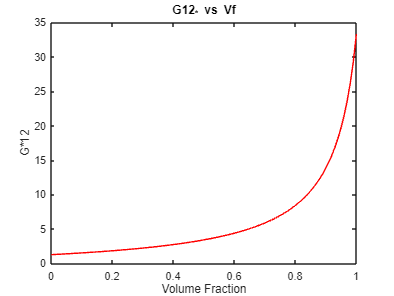

% Mori_Tanaka
clear all;
format long e
% Volume fraction
syms Vf
t = linspace(0,1,100);
  % Vf = 0.5;
   Vm = 1.0 - Vf;
% Now calculate the stiffness matrix of fibre
% Fibre is transversely isotropic with following properties in GPa
  E1 = 80;
  E2 = 80;
  E3 = E2;
%
  G12 = 33.33;
  G13 = 33.33;
%
  G23 = 33.33;
%  
  nu_12 = 0.2;
  nu_13 = nu_12;
%  
  nu_23 = E2/(2.0 * G23) - 1.0;
%
  nu_21 = nu_12 * E2/E1;
  nu_31 = nu_13 * E3/E1;
  nu_32 = nu_23 * E3/E2;
% Initialization
  s = zeros(6,6);
  Cf = zeros(6,6);
  Cm = zeros(6,6);
%  
    s(1,1)=1.0/E1;
    s(2,2)=1.0/E2;
    s(3,3)=1.0/E3;
%    
    s(1,2)=-nu_21/E2;
    s(1,3)=-nu_31/E3;
%    
    s(2,1)=-nu_21/E2;
    s(2,3)=-nu_32/E3;
%    
    s(3,1)=-nu_13/E1; 
    s(3,2)=-nu_23/E2;
% Following order is according order in Abaqus
    s(4,4)=1.0/G12;
    s(5,5)=1.0/G13;
    s(6,6)=1.0/G23;
    Cf = inv(s);
% Calculate the stiffness matrix of matrix
% Matrix is isotropic with following properties
  E0 = 3.35;
  XNU = 0.35;
%  
     XX = E0 * (1.0 - XNU)/((1.0 - 2.0 * XNU)*(1.0 + XNU));
     YY = E0 * XNU/((1.0 - 2.0 * XNU)*(1.0 + XNU));
     ZZ = E0 /(2.0 * (1.0 + XNU));
%
            for I = 1:3
               for J = 1:3
                  Cm(I,J) = YY;
               end
               Cm(I,I) = XX;
               Cm(I+3,I+3) = ZZ;
            end


nm=Cm(1,1);
lm=Cm(2,1);
mm=Cm(6,6);
pm=Cm(5,5);
km=Cm(2,2)-Cm(6,6);
nf=Cf(1,1);
lf=Cf(2,1);
mf=Cf(6,6);
pf=Cf(5,5);
kf=Cf(2,2)-Cf(6,6);

k = (Vf*kf*(km+mm)+Vm*km*(kf+mm))/(Vf*(km+mm)+Vm*(kf+mm));

l = (Vf*lf*(km+mm)+Vm*lm*(kf+mm))/(Vf*(km+mm)+Vm*(kf+mm));

n = Vm*nm+Vf*nf+(1-Vf*lf-Vm*lm)*((lf-lm)/(kf-mm));

m = (mf*mm*(kf+2*mm)+km*mm*(Vf*mf+Vm*mm))/(km*mm+(km+2*mm)*(Vf*mm+Vm*mf));

p = (2*Vf*pm*pf+Vm*(pm*pf+pm^2))/(2*Vf*pm+Vm*(pf+pm));

G12_eff = p;
G12_eff = double(subs(G12_eff,Vf,t));
plot(t,G12_eff,'r','Linewidth',0.2);
title("G12_* vs Vf")
xlabel("Volume Fraction")
ylabel("G*12")

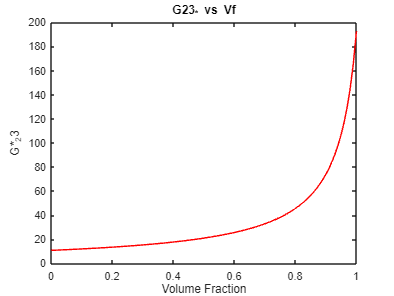


G23_eff = m;
G23_eff = double(subs(G23_eff,Vf,t));
plot(t,G23_eff,'r','Linewidth',0.2);
title("G23_* vs Vf")
xlabel("Volume Fraction")
ylabel("G*_23")

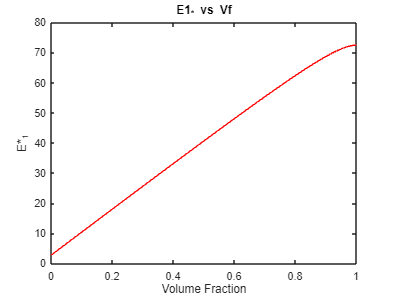


E1_eff = n - (l^2)/k;
E1_eff = double(subs(E1_eff,Vf,t));
plot(t,E1_eff,'r','Linewidth',0.2);
title("E1_* vs Vf")
xlabel("Volume Fraction")
ylabel("E*_1")

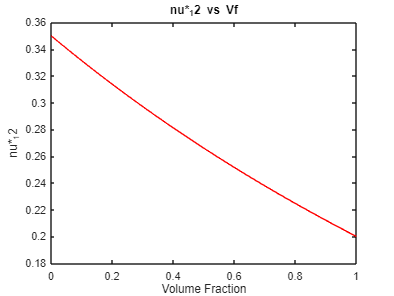


nu12_eff = l/(2*k);
nu12_eff = double(subs(nu12_eff,Vf,t));
plot(t,nu12_eff,'r','Linewidth',0.2);
title("nu*_12 vs Vf")
xlabel("Volume Fraction")
ylabel("nu*_12")

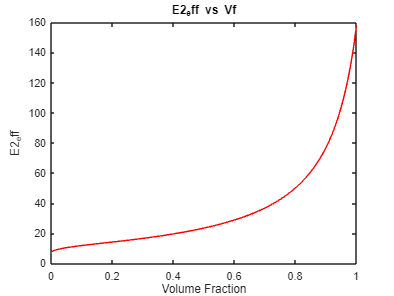



q = 1+(4*k*(l/(2*k))^2)/(n-(l^2)/k);
E2_eff = 4*k*m/(k+q*m);
E2_eff = double(subs(E2_eff,Vf,t));
plot(t,E2_eff,'r','Linewidth',0.2);
title("E2_eff vs Vf")
xlabel("Volume Fraction")
ylabel("E2_eff")

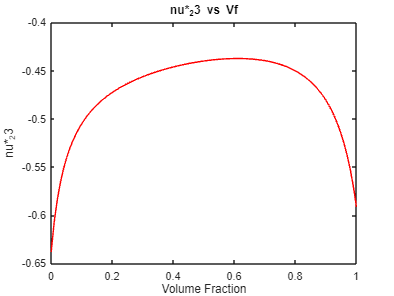


nu23_eff = (k-q*m)/(k+q*m);
nu23_eff = double(subs(nu23_eff,Vf,t));
plot(t,nu23_eff,'r','Linewidth',0.2);
title("nu*_23 vs Vf")
xlabel("Volume Fraction")
ylabel("nu*_23")